% import Training Data

dataSVM_feat = Training_Dataset;

% String values to b stored as integer codes

dataSVM_feat.Class = categorical(dataSVM_feat.Class);
dataSVM_feat.Class = grp2idx(dataSVM_feat.Class);
dataSVM_feat = table2array(dataSVM_feat);

% Random data sampling

index = randsample(1:length(dataSVM_feat), 1500);
train_dat = dataSVM_feat;
train_dat(index, :) = [];
test = dataSVM_feat(index, :);

% Columns to be trained
61, 124, 187, 250, 189, 53, 63, 9, 179, 7, 54, 72, 162, 135, 126

% Achieving target points for 15 defined features

targets = train_dat(:, end);
inputs_feat = train_dat(:,[61, 124, 187, 250, 189, 53, 63, 9, 179, 7, 54, 72, 162, 135, 126]);
targets_test = test(:, end);
inputs_feat_test = test(:, [61, 124, 187, 250, 189, 53, 63, 9, 179, 7, 54, 72, 162, 135, 126]);

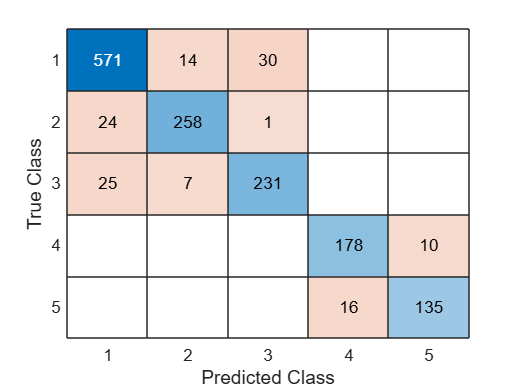

% Taking the Kernel Function with the most accuracy- 
% Linear Kernel Function: Box Constraint-100

model_feat = templateSVM("KernelFunction", "linear", "BoxConstraint", 100);
svm_feat = fitcecoc(inputs_feat, targets, 'Learners', model_feat);
tstOutputs_feat = predict(svm_feat, inputs_feat_test);
[c_feat, cm_feat] = confusionmat(targets_test', tstOutputs_feat');
accuracy_feat = sum(diag(c_feat))/sum(c_feat(:));
confusionchart(targets_test', tstOutputs_feat');

disp(accuracy_feat);

    0.9153

